# EE3320 - Wireless Communications

# Assignment-4

#### EE18BTECH11014

#### Krishna Srikar Durbha

## Signal and Channel Parameters

% No.of Samples
N = 100000;

% SNR(in dBW)
SNR = linspace(-5,10,6); 

## BPSK Modulation

Generating Signal

tx = randi([0 1],N,1);

Probability of Error

Pe_AWGN = BitErrorRate(tx,"BPSK","AWGN",SNR);
Pe_Rayleigh = BitErrorRate(tx,"BPSK","Rayleigh",SNR);
Pe_Nakagami = BitErrorRate(tx,"BPSK","Nakagami",SNR);
Pe_Rician = BitErrorRate(tx,"BPSK","Rician",SNR);

Plots

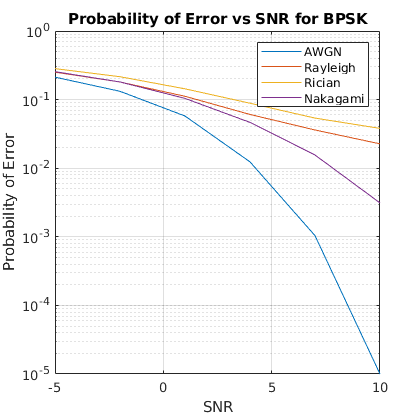

semilogy(SNR,Pe_AWGN,SNR,Pe_Rayleigh,SNR,Pe_Rician,SNR,Pe_Nakagami)
title("Probability of Error vs SNR for BPSK")
ylabel('Probability of Error') 
xlabel('SNR')
legend({'AWGN','Rayleigh','Rician','Nakagami'})
grid on;

## 16-QAM Modulation

Generating Signal

tx = randi([0 1],N,1);

Probability of Error

Pe_AWGN = BitErrorRate(tx,"16-QAM","AWGN",SNR);
Pe_Rayleigh = BitErrorRate(tx,"16-QAM","Rayleigh",SNR);
Pe_Nakagami = BitErrorRate(tx,"16-QAM","Nakagami",SNR);
Pe_Rician = BitErrorRate(tx,"16-QAM","Rician",SNR);

Plots

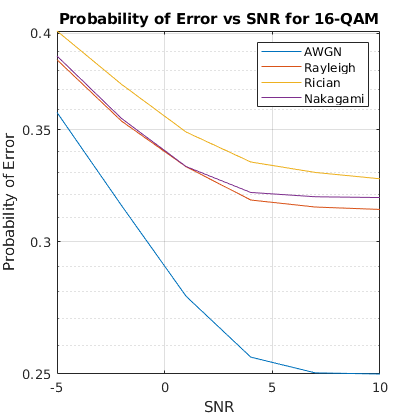

semilogy(SNR,Pe_AWGN,SNR,Pe_Rayleigh,SNR,Pe_Rician,SNR,Pe_Nakagami)
title("Probability of Error vs SNR for 16-QAM")
ylabel('Probability of Error') 
xlabel('SNR')
legend({'AWGN','Rayleigh','Rician','Nakagami'})
grid on;

## Functions

### Bit Error Rate Calculation for a Signal

function BERs = BitErrorRate(tx,Modulation,Channel,SNR)

    % Modulation: Modulating Data and Scatter Plotting it
    if Modulation == "BPSK"
        bpskModulator = comm.BPSKModulator;
        txModulated = bpskModulator(tx);
        %scatterplot(txModulated);
        %grid on;
    elseif Modulation == "16-QAM"
        txModulated = Bits2Symbols(tx);
        txModulated = qammod(txModulated,16);
        %scatterplot(txModulated);
        %grid on;
    end
    
    N = size(txModulated,1);
    S = size(SNR,2);
    
    % Transmission: Transmission of Data through Channel and
    % Decoding: Decoding the Received Data
    BERs = zeros(1,S);
    for i = 1:S
        % Fading and Noise
        if Channel == "Rayleigh"
            b = 0.5;
            h = pdf("Rayleigh",linspace(0,1,N)',b);
            rx = awgn(h.* txModulated,SNR(i));            
        elseif Channel == "Rician"
            v = 0.5;
            s = 0.5;
            h =  pdf("Rician",linspace(0,1,N)',v,s);
            rx = awgn(h.* txModulated,SNR(i));            
        elseif Channel == "Nakagami"
            mu = 0.5;
            w = 0.5;
            h =  pdf("Nakagami",linspace(0,1,N)',mu,w);
            rx = awgn(h.* txModulated,SNR(i));  
        elseif Channel == "AWGN"
            rx = awgn(txModulated,SNR(i)); 
        end
        
        
        % Decode: Decoding Data
        if Modulation == "BPSK"
            rxDecoded = BPSKDecode(rx);
        elseif Modulation == "16-QAM"
            rxDecoded = QAM16Decode(rx);
        end
    
        
        % DeModulate: Demodulating Data
        if Modulation == "BPSK"
            bpskDeModulator = comm.BPSKDemodulator;
            rxDeModulated = bpskDeModulator(rxDecoded);
        elseif Modulation == "16-QAM"
            rxDeModulated = qamdemod(rxDecoded,16);
            rxDeModulated = Symbols2Bits(rxDeModulated);
        end
        
        
        % Bit Error Rate
        BERs(i) = BER(tx,rxDeModulated);
    end
end

### BSPK Decoding

function o = BPSKDecode(rx)
    tr = [0:1]';
    bpskModulator = comm.BPSKModulator;
    ref = bpskModulator(tr);
    
    N = size(rx,1);
    o = zeros(N,1);
    
    for i=1:N
        [M,I] = min(abs(dist(ref,rx(i))));
        o(i) = ref(I);
    end
end

### 16-QAM Decoding

function o = QAM16Decode(rx)
    tr = [0:15]';
    ref = qammod(tr,16);
    
    N = size(rx,1);
    o = zeros(N,1);
    
    for i=1:N
        [M,I] = min(abs(dist(ref,rx(i))));
        o(i) = ref(I);
    end
end

### Bit Error Rate

function p = BER(tx,rx)
    N = size(tx,1);
    p = sum(abs(tx-rx))/N;
end

### 16-QAM Maps

% Symbol to Bits Map
function rx = Symbols2Bits(sym)
    N = size(sym,1);
    rxr = zeros(N,4);
    for i=1:N
        if sym(i) == 0
            rxr(i,1:4) = [0,0,0,0];
        elseif sym(i) == 1
            rxr(i,1:4) = [0,0,0,1];
        elseif sym(i) == 2
            rxr(i,1:4) = [0,0,1,0];
        elseif sym(i) == 3
            rxr(i,1:4) = [0,0,1,1];
        elseif sym(i) == 4
            rxr(i,1:4) = [0,1,0,0];
        elseif sym(i) == 5
            rxr(i,1:4) = [0,1,0,1];
        elseif sym(i) == 6
            rxr(i,1:4) = [0,1,1,0];
        elseif sym(i) == 7 
            rxr(i,1:4) = [0,1,1,1];
        elseif sym(i) == 8
            rxr(i,1:4) = [1,0,0,0];
        elseif sym(i) == 9
            rxr(i,1:4) = [1,0,0,1];
        elseif sym(i) == 10
            rxr(i,1:4) = [1,0,1,0];
        elseif sym(i) == 11
            rxr(i,1:4) = [1,0,1,1];
        elseif sym(i) == 12
            rxr(i,1:4) = [1,1,0,0];
        elseif sym(i) == 13
            rxr(i,1:4) = [1,1,0,1];
        elseif sym(i) == 14
            rxr(i,1:4) = [1,1,1,0];
        elseif sym(i) == 15
            rxr(i,1:4) = [1,1,1,1];
        end
    end
    rx = reshape(rxr',[4*N,1]);
end

% Bits to Symbol Map
function sym = Bits2Symbols(tx)
    N = size(tx,1);
    t = reshape(tx,[4, N/4]);
    txr = t';
    sym = zeros(N/4,1);
    for i=1:N/4
        if txr(i,1:4) == [0,0,0,0]
            sym(i) = 0;
        elseif txr(i,1:4) == [0,0,0,1]
            sym(i) = 1;
        elseif txr(i,1:4) == [0,0,1,0]
            sym(i) = 2;
        elseif txr(i,1:4) == [0,0,1,1]
            sym(i) = 3;
        elseif txr(i,1:4) == [0,1,0,0]
            sym(i) = 4;
        elseif txr(i,1:4) == [0,1,0,1]
            sym(i) = 5;
        elseif txr(i,1:4) == [0,1,1,0]
            sym(i) = 6;
        elseif txr(i,1:4) == [0,1,1,1]
            sym(i) = 7;
        elseif txr(i,1:4) == [1,0,0,0]
            sym(i) = 8;
        elseif txr(i,1:4) == [1,0,0,1]
            sym(i) = 9;
        elseif txr(i,1:4) == [1,0,1,0]
            sym(i) = 10;
        elseif txr(i,1:4) == [1,0,1,1]
            sym(i) = 11;
        elseif txr(i,1:4) == [1,1,0,0]
            sym(i) = 12;
        elseif txr(i,1:4) == [1,1,0,1]
            sym(i) = 13;
        elseif txr(i,1:4) == [1,1,1,0]
            sym(i) = 14;
        elseif txr(i,1:4) == [1,1,1,1]
            sym(i) = 15;
        end
    end
end